Fig 4.8(1)

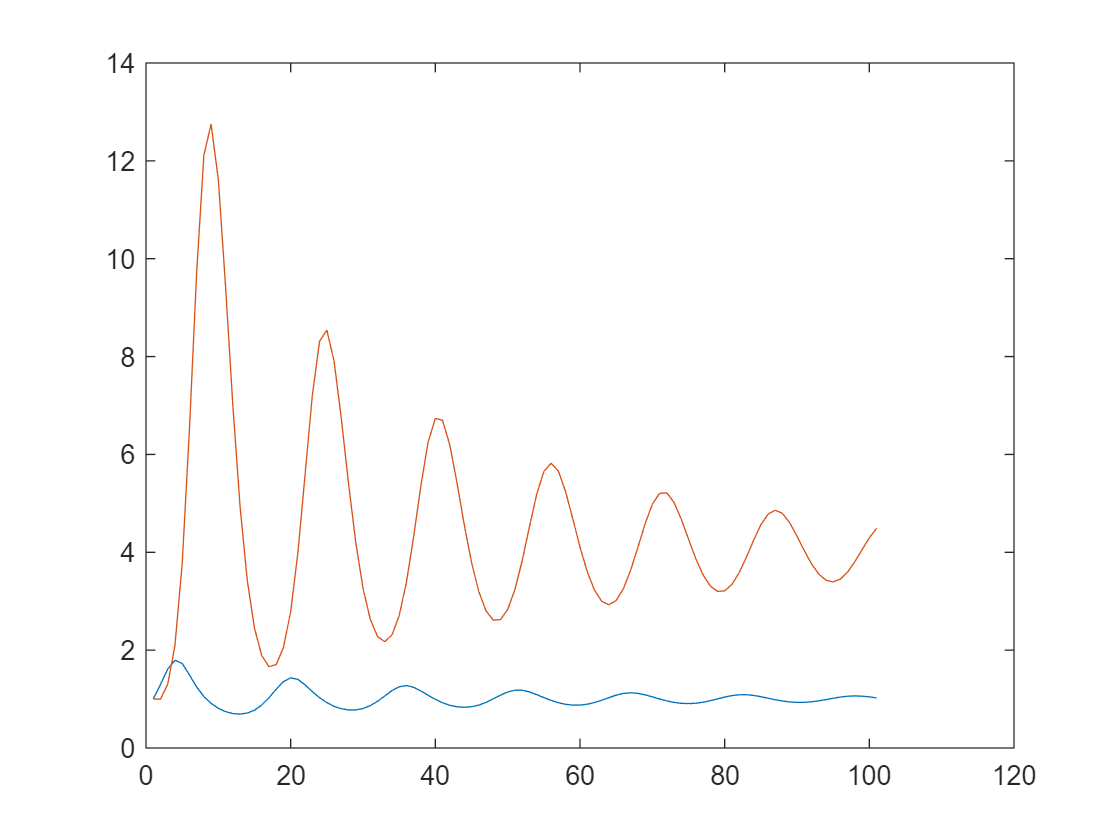

r=1;
b=1;
c=1;
d=1;
s=100;
X=zeros(1,s);                                                         %建立一行s列的零矩阵X
Y=zeros(1,s);
X(1,1)=1;                                                             %第一行第一列元素为1
Y(1,1)=1;
for t=1:1:100
        X(1,t+1)=X(1,t)+X(1,t).*(r-1+1./(b.*Y(1,t)+1)-X(1,t)./5);
        Y(1,t+1)=(1-d).*Y(1,t)+c.*Y(1,t).*X(1,t);
end
plot(X)
hold on
plot(Y)
hold off

Fig 4.8(2)

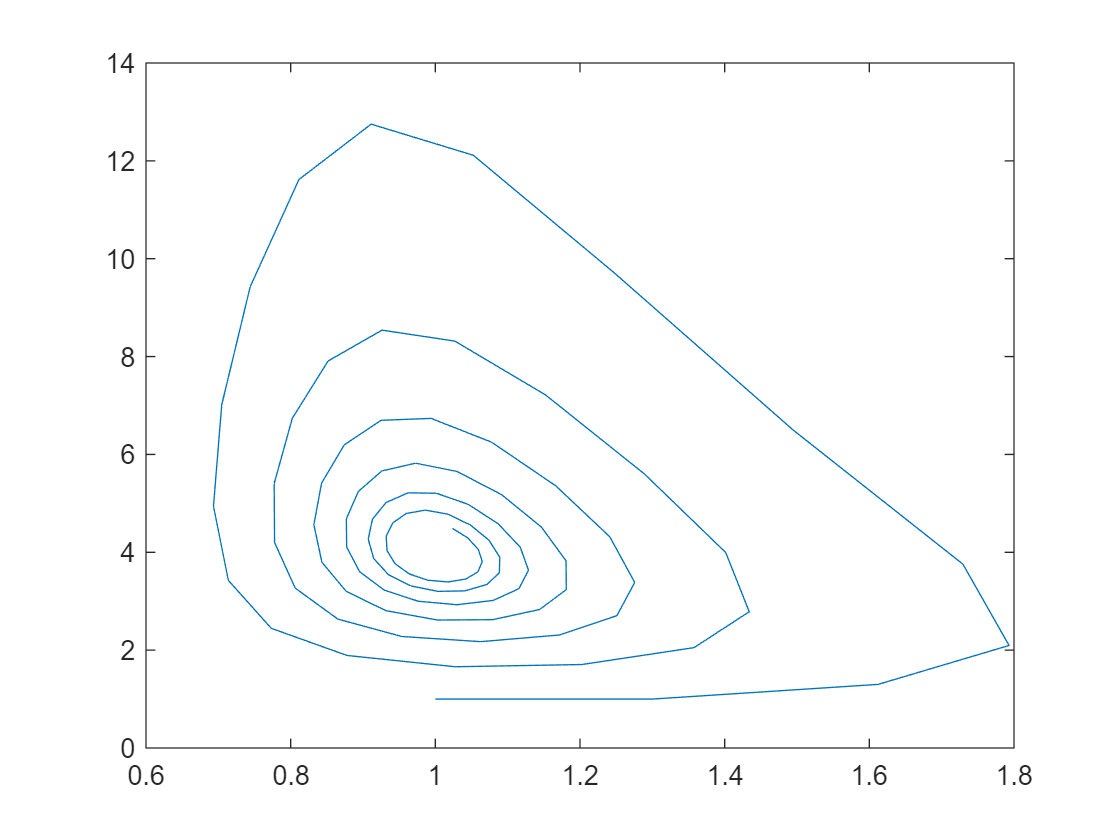

r=1;
b=1;
c=1;
d=1;
s=100;
X=zeros(1,s);
Y=zeros(1,s);
X(1,1)=1;
Y(1,1)=1;
for t=1:1:100
       X(1,t+1)=X(1,t)+X(1,t).*(r-1+1./(b.*Y(1,t)+1)-X(1,t)./5);
        Y(1,t+1)=(1-d).*Y(1,t)+c.*Y(1,t).*X(1,t);
end
plot(X,Y);

Fig 5.1

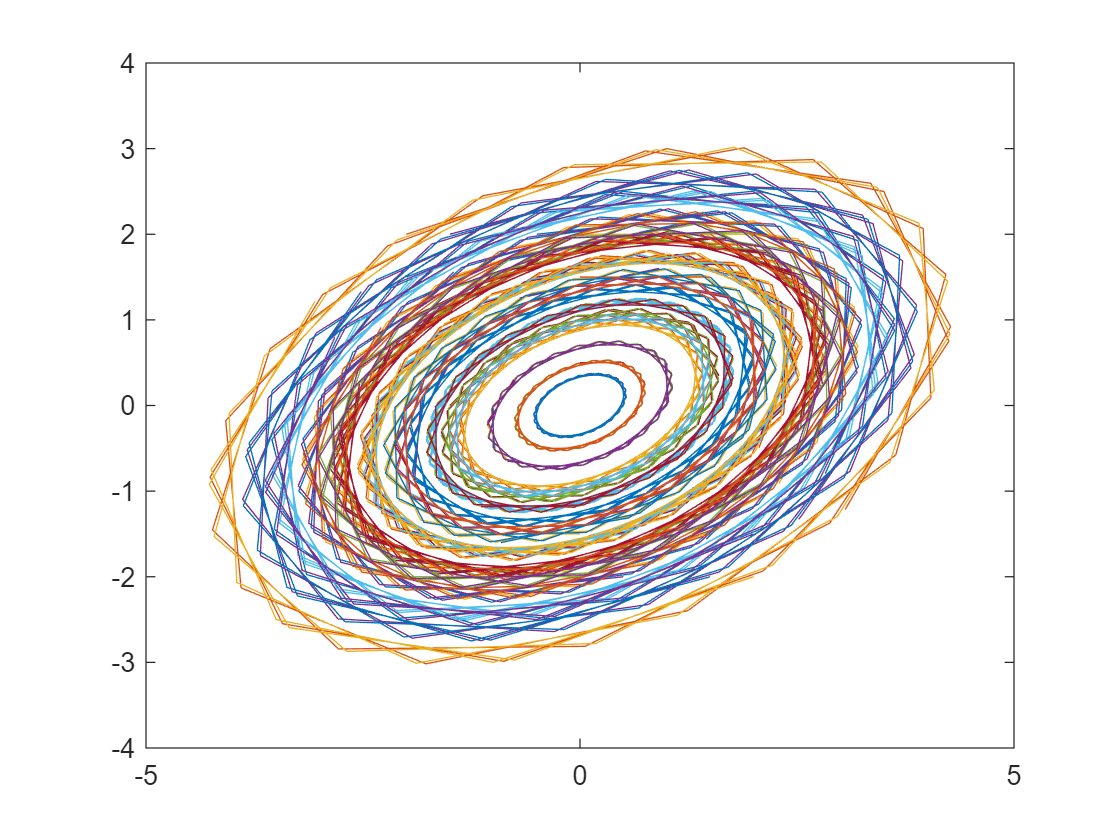

s=30;
X=zeros(1,s);
Y=zeros(1,s);
for x0=-2:0.5:2
    for y0=-2:0.5:2
        X(1,1)=x0;
        Y(1,1)=y0;
        for t=1:s
            X(1,t+1)=0.5.*X(1,t)+Y(1,t);
            Y(1,t+1)=-0.5.*X(1,t)+Y(1,t);
        end
        plot(X,Y)
        hold on;
    end
end
hold off;

Fig 5.2

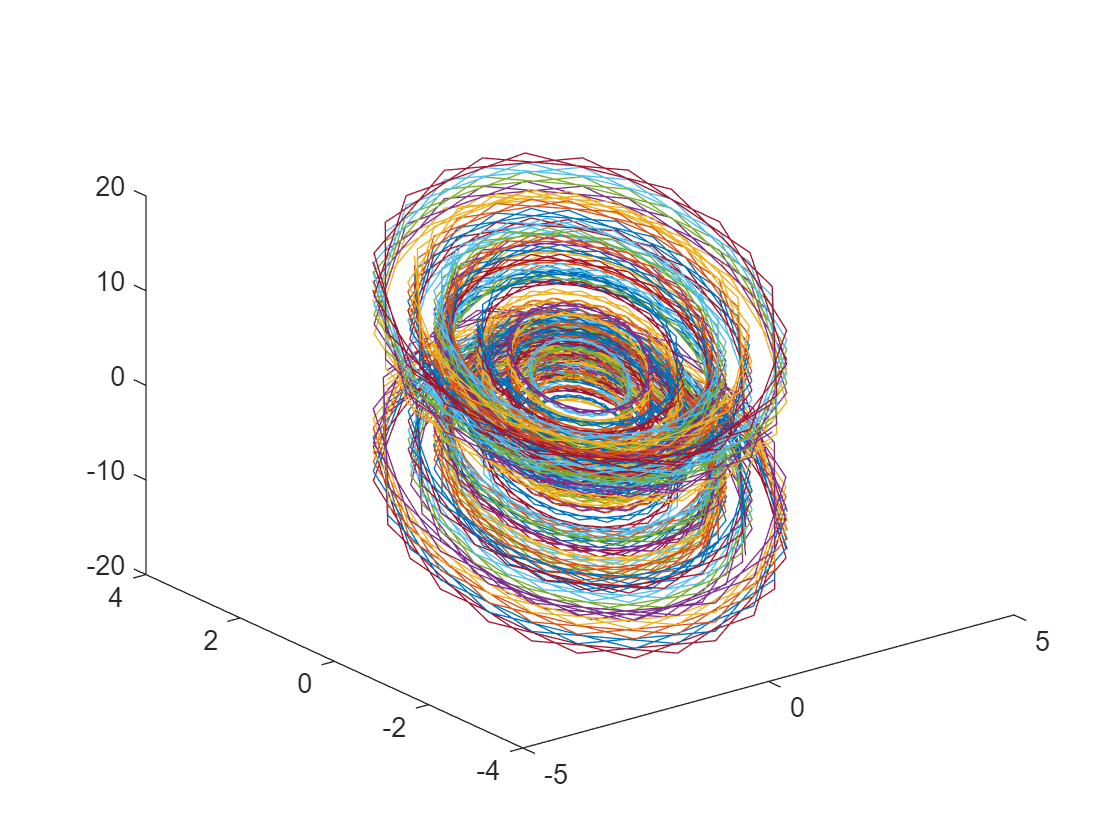

s=30;
X=zeros(1,s);
Y=zeros(1,s);
Z=zeros(1,s);
for x0=-2:1:2
    for y0=-2:1:2
        for z0=-2:1:2
        X(1,1)=x0;
        Y(1,1)=y0;
        Z(1,1)=z0;
        for t=1:s
            X(1,t+1)=0.5.*X(1,t)+Y(1,t);
            Y(1,t+1)=-0.5.*X(1,t)+Y(1,t);
            Z(1,t+1)=-1*X(1,t)+(-1)*Y(1,t)+Z(1,t);
        end
        plot3(X,Y,Z)
        hold on;
        end
    end
end
hold off;

Fig 5.3

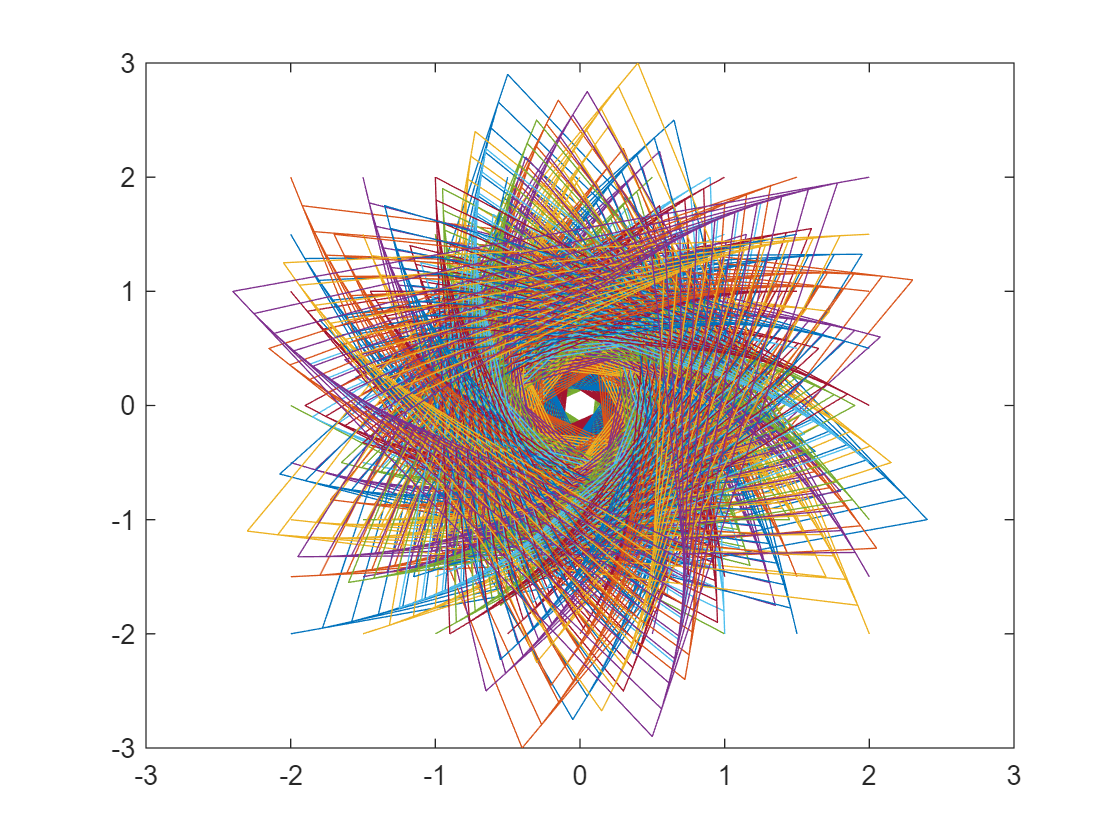

s=30;
X=zeros(1,s);
Y=zeros(1,s);
for x0=-2:0.5:2
    for y0=-2:0.5:2
        X(1,1)=x0;
        Y(1,1)=y0;
        for t=1:s
            X(1,t+1)=-0.5.*X(1,t)+-0.7.*Y(1,t);
            Y(1,t+1)=X(1,t)+-0.5.*Y(1,t);
        end
        plot(X,Y)
        hold on;
    end
end
hold off;